# Franka Emika Panda Singularities Set4

clc; clear; close;

#### Define the transformation matrices for the Franka Emika Panda Robot / Configuration1

M = [[1, 0, 0, 0.088];[0, -1, 0, 0];[0, 0, -1, 0.926];[0, 0, 0, 1]];
vpa(M, 4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0.088\\ 0 & -1.0 & 0 & 0\\ 0 & 0 & -1.0 & 0.926\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

S = [[0;0;1;0;0;0],[0;1;0;-0.333;0;0],[0;0;1;0;0;0],[0;-1;0;0.316+0.333;0;-0.0825],[0;0;1;0;0;0],[0;-1;0;0.384+0.316+0.333;0;0],[0;0;-1;0;0.088;0]];
vpa(S, 4)

$$ans = \left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1.0 & 0 & -1.0 & 0 & -1.0 & 0\\ 1.0 & 0 & 1.0 & 0 & 1.0 & 0 & -1.0\\ 0 & -0.333 & 0 & 0.649 & 0 & 1.033 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0.088\\ 0 & 0 & 0 & -0.0825 & 0 & 0 & 0 \end{array}\right)$$

#### Defining joint limits 

qlim = [-2.8973, 2.8973; -1.7628, 1.7628; -2.8973, 2.8973; -3.0718, -0.0698; -2.8973, 2.8973; -0.0175, 3.7525; -2.8973, 2.8973];

vpa(qlim, 5)

$$ans = \left(\begin{array}{cc} -2.8973 & 2.8973\\ -1.7628 & 1.7628\\ -2.8973 & 2.8973\\ -3.0718 & -0.0698\\ -2.8973 & 2.8973\\ -0.0175 & 3.7525\\ -2.8973 & 2.8973 \end{array}\right)$$

#### Generate a set of discrete joint angles within the joint limits

for i=1:size(qlim, 1)
    Qlim(i, :) = linspace(qlim(i, 1), qlim(i, 2), 10);
end
Qlim

Qlim =    -2.8973   -2.2535   -1.6096   -0.9658   -0.3219    0.3219    0.9658    1.6096    2.2535    2.8973
   -1.7628   -1.3711   -0.9793   -0.5876   -0.1959    0.1959    0.5876    0.9793    1.3711    1.7628
   -2.8973   -2.2535   -1.6096   -0.9658   -0.3219    0.3219    0.9658    1.6096    2.2535    2.8973
   -3.0718   -2.7382   -2.4047   -2.0711   -1.7376   -1.4040   -1.0705   -0.7369   -0.4034   -0.0698
   -2.8973   -2.2535   -1.6096   -0.9658   -0.3219    0.3219    0.9658    1.6096    2.2535    2.8973
   -0.0175    0.4014    0.8203    1.2392    1.6581    2.0769    2.4958    2.9147    3.3336    3.7525
   -2.8973   -2.2535   -1.6096   -0.9658   -0.3219    0.3219    0.9658    1.6096    2.2535    2.8973


#### **Solving Singularity equation with DH Parameters**

a1 = 0; a2 = 0; a3 = 0; a4 = 0.0825;
a5 = -0.0825; a6 = 0; a7 = 0.088; aF = 0;
d1 = 0.333; d2 = 0; d3 = 0.316; d4 = 0;
d5 = 0.384; d6 = 0; d7 = 0; dF = 0.107;
syms th4
syms th3
syms th5
syms th6
x = tan(th4);
y = sqrt(1 + tan(th4)^2);
eq = -a5*(x^2*a5 + y*x*d3 + (1 - y)*a5)*...
      cos(th3)*a7*cos(th5)^2 + a5*sin(th3)*(x^2*a5 + y*x*d3 + (1 - y)*a5)*...
      a7*sin(th5)*cos(th5) - [sin(th6)*((a5^2 -d5*d3)*x + (d3 + d5)*a5) - a7*(d3*x - a5)]*cos(th3)*(y*a5 + d5*x - a5);
vpa(eq,4)

$$ans = \begin{array}{l} 0.088\,\cos\left({\mathrm{th}}_{3}\right)\,\left(0.006806\,\sigma_{1}-0.006806\,{\tan\left({\mathrm{th}}_{4}\right)}^{2}+0.02607\,\tan\left({\mathrm{th}}_{4}\right)\,\sigma_{1}-0.006806\right)\,{\cos\left({\mathrm{th}}_{5}\right)}^{2}-0.00726\,\sin\left({\mathrm{th}}_{3}\right)\,\sin\left({\mathrm{th}}_{5}\right)\,\left(0.0825\,\sigma_{1}-0.0825\,{\tan\left({\mathrm{th}}_{4}\right)}^{2}+0.316\,\tan\left({\mathrm{th}}_{4}\right)\,\sigma_{1}-0.0825\right)\,\cos\left({\mathrm{th}}_{5}\right)+\cos\left({\mathrm{th}}_{3}\right)\,\left(0.384\,\tan\left({\mathrm{th}}_{4}\right)-0.0825\,\sigma_{1}+0.0825\right)\,\left(0.02781\,\tan\left({\mathrm{th}}_{4}\right)+\sin\left({\mathrm{th}}_{6}\right)\,\left(0.1145\,\tan\left({\mathrm{th}}_{4}\right)+0.05775\right)+0.00726\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\tan\left({\mathrm{th}}_{4}\right)}^{2}+1.0} \end{array}$$

#### This equation has infinite number of solutions.

#### To simplify, first we consider $\theta_4 = -1.5$ and $\theta_5 = 3$.

#### Now, we can plot the equation as a function of $\theta_4$ & $\theta_6$.

th4 = -1.5;
th5 = 3;
x = tan(th4);
y = sqrt(1 + tan(th4)^2);
f=@(th3,th6) -a5*(x^2*a5 + y*x*d3 + (1 - y)*a5)*...
      cos(th3)*a7*cos(th5)^2 + a5*sin(th3)*(x^2*a5 + y*x*d3 + (1 - y)*a5)*...
      a7*sin(th5)*cos(th5) - [sin(th6)*((a5^2 -d5*d3)*x + (d3 + d5)*a5) - a7*(d3*x - a5)]*cos(th3)*(y*a5 + d5*x - a5);
fimplicit(f,[-176/180*pi -166/180*pi -1/180*pi 215/180*pi])

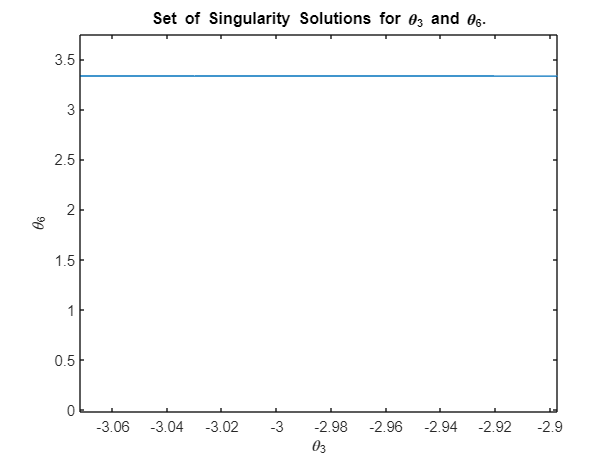

title('Set of Singularity Solutions for \theta_3 and \theta_6.');
xlabel('\theta_3');
ylabel('\theta_6');

#### For any value of $\theta_3$, $\theta_6$ should be 3.331368.

th3 = -3;
S_eq4 = vpa(solve(-a5*(x^2*a5 + y*x*d3 + (1 - y)*a5)*...
      cos(th3)*a7*cos(th5)^2 + a5*sin(th3)*(x^2*a5 + y*x*d3 + (1 - y)*a5)*...
      a7*sin(th5)*cos(th5) - [sin(th6)*((a5^2 -d5*d3)*x + (d3 + d5)*a5) - a7*(d3*x - a5)]*cos(th3)*(y*a5 + d5*x - a5) == 0,th6),10)

$$S\_eq4 = \left(\begin{array}{c} -0.1921285628\\ 3.333721216 \end{array}\right)$$

#### Define Singular Configurations (Define all possible configs)

Q1 = Qlim(1, :);
Q2 = [0];
Q3 = [-3];
Q4 = [-1.5];
Q5 = [3];
Q6 = [S_eq4(2)];
Q7 = Qlim(7, :);

#### Generate all possible combinations of joint angles for the robot

Q = unique(combvec(Q1, Q2, Q3, Q4, Q5, Q6, Q7)', 'rows');
Q

Q =    -2.8973         0   -3.0000   -1.5000    3.0000    3.3337   -2.8973
   -2.8973         0   -3.0000   -1.5000    3.0000    3.3337   -2.2535
   -2.8973         0   -3.0000   -1.5000    3.0000    3.3337   -1.6096
   -2.8973         0   -3.0000   -1.5000    3.0000    3.3337   -0.9658
   -2.8973         0   -3.0000   -1.5000    3.0000    3.3337   -0.3219
   -2.8973         0   -3.0000   -1.5000    3.0000    3.3337    0.3219
   -2.8973         0   -3.0000   -1.5000    3.0000    3.3337    0.9658
   -2.8973         0   -3.0000   -1.5000    3.0000    3.3337    1.6096
   -2.8973         0   -3.0000   -1.5000    3.0000    3.3337    2.2535
   -2.8973         0   -3.0000   -1.5000    3.0000    3.3337    2.8973


#### Remove duplicate joint angles

uniqueQ = unique(Q, 'rows');
numDuplicates = size(Q,1) - size(uniqueQ,1)

numDuplicates = 0

####  Compute the forward kinematics for each unique set of joint angles

for i = 1:size(uniqueQ,1)
    T1 = FK_SpaceForm(S, M, uniqueQ(i, 1: 7)');
    X(i) = T1(1, 4);
    Y(i) = T1(2, 4);
    Z(i) = T1(3, 4);
end

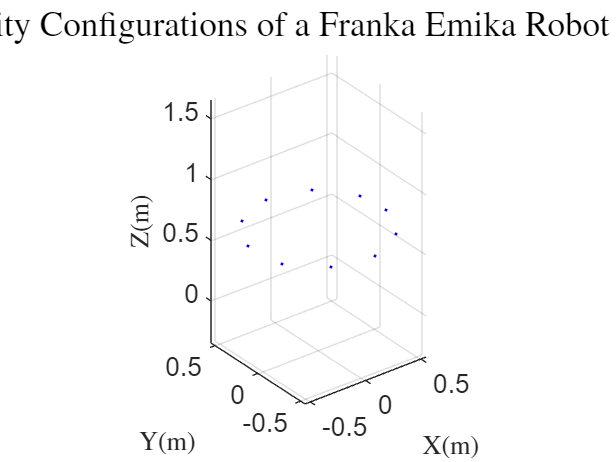

%distance = sqrt(X.^2 + Y.^2 + Z.^2); % compute distance from origin
%c = distance/max(distance); % normalize distances to [0,1]

scatter3(X, Y, Z, 'b.');
% colormap jet; % set the color map
% colorbar; % add a color bar to the plot
ax = gca;
ax.FontSize = 18;
xlabel('X(m)', 'FontSize', 18, 'Interpreter','latex');
ylabel('Y(m)', 'FontSize', 18, 'Interpreter','latex');
zlabel('Z(m)', 'FontSize', 18, 'Interpreter','latex');
title('Singularity Configurations of a Franka Emika Robot (Config 4)', 'FontSize', 24, 'Interpreter','latex');
axis equal;

%view(0,0);

#### Choose an arbitrary config to visualize

Q1_rndm = Q1(randi(numel(Q1)));
Q2_rndm = [0];
Q3_rndm = [-3];
Q4_rndm = [-1.5];
Q5_rndm = [3];
Q6_rndm = [S_eq4(2)];
Q7_rndm = Q7(randi(numel(Q7)));

thetas = unique(combvec(Q1_rndm, Q2_rndm, Q3_rndm, Q4_rndm, Q5_rndm, Q6_rndm, Q7_rndm)', 'rows');
thetas

thetas =     2.2535         0   -3.0000   -1.5000    3.0000    3.3337    0.3219


Js =          0   -0.7759         0   -0.6791    0.7322    0.6796    0.7102
         0   -0.6309         0   -0.7340   -0.6774    0.7199   -0.6938
    1.0000         0    1.0000         0    0.0707   -0.1408   -0.1191
         0    0.2101         0    0.4764    0.4917   -0.5021    0.5036
         0   -0.2584         0   -0.4407    0.5315    0.5630    0.5155
         0         0         0   -0.0825         0    0.4551    0.0000


ans = 5

2 linearly dependent joints:
  q3 depends on: q1 
  q7 depends on: q1 q2 q3 q4 q5 


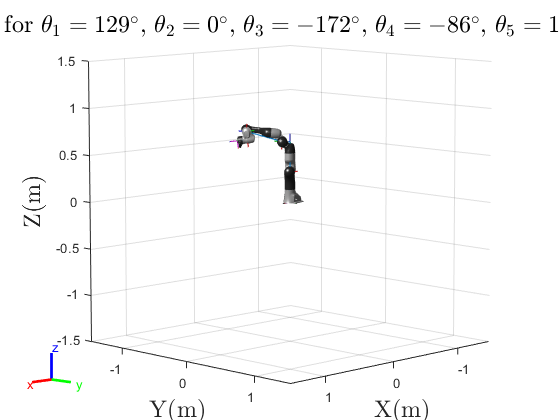


for theta = thetas'
    Js = J_SpaceForm(S, theta)
    rank(Js)
    jsingu(Js)
    robot = importrobot('Franka_Emika_Panda.urdf');
    robot.DataFormat = 'column';

    figure;

    str = "Singular Configuration for ";
    for i= 1:numel(theta)
        str = str + "$\theta_" + num2str (i) + "=" +num2str(round(rad2deg(theta(i)))) + "^ \circ $, ";
    end

    show(robot,theta,'Visuals','on','Frames','on');
    xlabel('X(m)', 'FontSize', 18, 'Interpreter','latex');
    ylabel('Y(m)', 'FontSize', 18, 'Interpreter','latex');
    zlabel('Z(m)', 'FontSize', 18, 'Interpreter','latex');

    title(str, 'FontSize', 18, 'Interpreter','latex');

end